datasetPath = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\speech_commands_v0.02";

ads = audioDatastore(datasetPath,'IncludeSubfolders', true, 'FileExtensions','.wav', 'LabelSource','foldernames');
countEachLabel(ads)

ans = 4×2 table
    Label    Count
    _____    _____

    go       3880 
    no       3941 
    stop     3872 
    yes      4044 


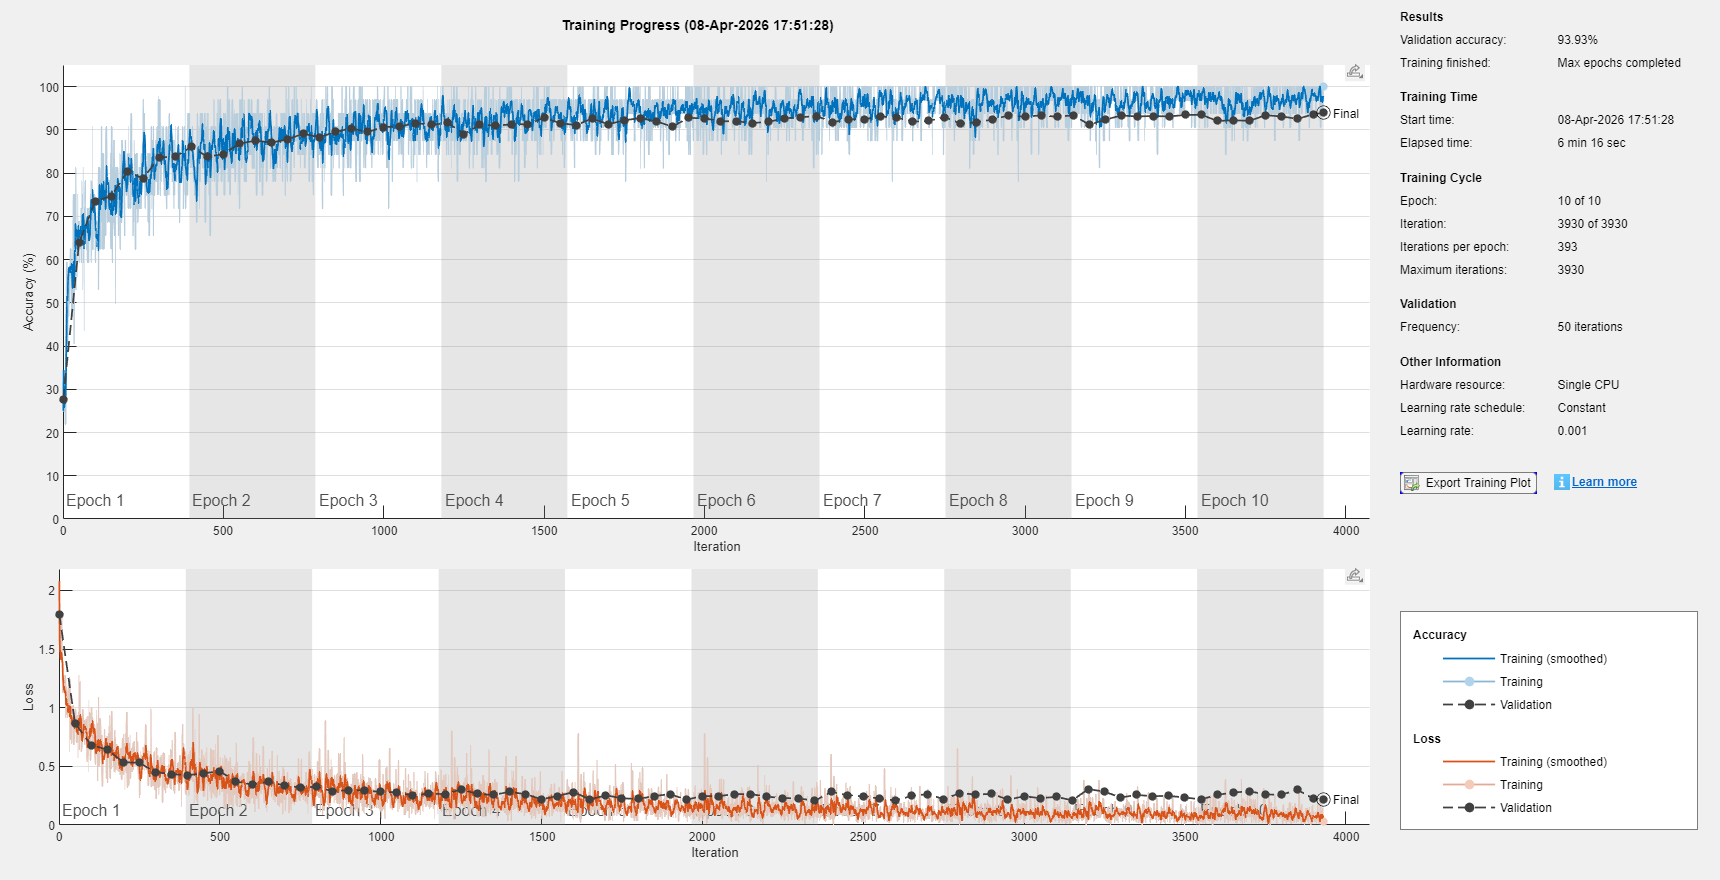


noisePath = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\_background_noise_";
noiseADS = audioDatastore(noisePath,'IncludeSubfolders', true,'FileExtensions', '.wav');

%Split into Training and Testing data
[adsTrain, adsTest] = splitEachLabel(ads, 0.8);

%remove unused labels (NOT USEFUL NOW)
%adsTrain.Labels = removecats(adsTrain.Labels);
%adsTest.Labels = removecats(adsTest.Labels);

%get mel spectrograms for all training files
numTrainFiles = numel(adsTrain.Files);
XTrain = zeros(64,64,1,numTrainFiles);
YTrain = adsTrain.Labels;

for i = 1:numTrainFiles
    [audio, fs] = audioread(adsTrain.Files{i});

    %---Noise stuff

    % Make sure command audio is exactly 1 second long
    targetLength = fs; % 1 second
    if length(audio) < targetLength
        audio = [audio; zeros(targetLength - length(audio), 1)];
    else
        audio = audio(1:targetLength);
    end
    
    % Randomly choose one background noise file
    noiseIndex = randi(numel(noiseADS.Files));
    [noiseAudio, noiseFs] = audioread(noiseADS.Files{noiseIndex});

    % Resample noise if needed
    if noiseFs ~= fs
        noiseAudio = resample(noiseAudio, fs, noiseFs);
    end

    % If stereo, convert to mono
    if size(noiseAudio,2) > 1
        noiseAudio = mean(noiseAudio, 2);
    end

    % Take a random 1-second chunk from the noise
    if length(noiseAudio) > fs
        startIdx = randi(length(noiseAudio) - fs + 1);
        noiseChunk = noiseAudio(startIdx:startIdx + fs - 1);
    else
        noiseChunk = [noiseAudio; zeros(fs - length(noiseAudio), 1)];
    end

    % Scale the background noise
    noiseScale = 0.05;   % try 0.02, 0.05, or 0.1
    audioNoisy = audio + noiseScale * noiseChunk;

    %---End of Noise stuff
    
    melSpec = melSpectrogram(audioNoisy, fs, 'NumBands',64);
    melSpec = log10(melSpec + 1e-6);
    
    melSpec = imresize(melSpec, [64 64]);
    
    XTrain(:,:,1,i) = melSpec;
end

%do same for test files
numTestFiles = numel(adsTest.Files);
XTest = zeros(64,64,1,numTestFiles);
YTest = adsTest.Labels;

for i = 1:numTestFiles
    [audio, fs] = audioread(adsTest.Files{i});
    
    melSpec = melSpectrogram(audio, fs, 'NumBands',64);
    melSpec = log10(melSpec + 1e-6);
    
    melSpec = imresize(melSpec, [64 64]);
    
    XTest(:,:,1,i) = melSpec;
end

%
layers = [
    %tells MATLAB each input is a 64×64 grayscale image
    imageInputLayer([64 64 1])

    %applies 8 filters to detect simple patterns in the spectrogram
    convolution2dLayer(3,8,Padding="same")
    batchNormalizationLayer

    %adds nonlinearity so the network can learn more than just simple linear patterns
    reluLayer

    %reduces the image size and keeps the strongest features
    maxPooling2dLayer(2,Stride=2)

    %Second layer
    convolution2dLayer(3,16,Padding="same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,Stride=2)

    %Third layer
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,Stride=2)

    %maps the extracted features to your command classes
    fullyConnectedLayer(numel(categories(YTrain)))

    %turns outputs into class probabilities
    softmaxLayer

    %computes the classification loss during training
    classificationLayer
];

%Setting Training Options
options = trainingOptions("adam","MaxEpochs", 10,"MiniBatchSize", 32,"ValidationData", {XTest, YTest},"Verbose", false, "Plots", "training-progress");

%save model when first ran then just load it once it's made so it doesnt
%keep training when not necessary

modelPath = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\speechCommandModelv2.mat";

if isfile(modelPath)
    load(modelPath)
else
    net = trainNetwork(XTrain,YTrain,layers,options);
    save(modelPath,"net")
end


%Test accuracy
YPred = classify(net, XTest);
accuracy = mean(YPred == YTest)

accuracy = 0.9393

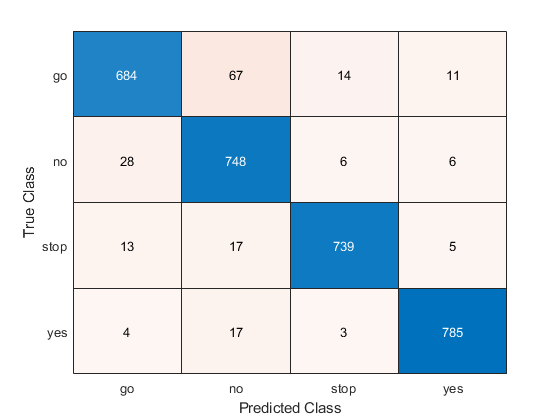


confusionchart(YTest,YPred)


%take a background noise file, break it down into 1 sec recordings
%use that as a class of training data

%SVM Model for Command Detection

clc; clear; close all;

%Load dataset
dataPath = "/Users/ericdutan/Desktop/Machine_learning/Project/Data_Set";

ads = audioDatastore(dataPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

%Extract features(MFC Mel-Frequency Cepstral Coefficients). These are handcrafted features
features = [];
labels = [];

for i = 1:length(ads.Files)
    
    % Read audio
    [audioIn, fs] = audioread(ads.Files{i});
    
    % Convert to mono if stereo
    if size(audioIn,2) > 1
        audioIn = mean(audioIn,2);
    end
    
    % Extract MFCCs
        %mfcc-> capture: pitch, tone, speech characteristics
    coeffs = mfcc(audioIn, fs);
    
    % Take mean and std (fixed-length feature vector)
    feat = [mean(coeffs), std(coeffs)];
    
    % Store
    features = [features; feat];
    labels = [labels; ads.Labels(i)];
end

%Split into training/testing (80/20)
cv = cvpartition(labels, 'HoldOut', 0.2);

XTrain = features(training(cv), :); %Training data inputs
YTrain = labels(training(cv));      %Corresponding training labels 

XTest = features(test(cv), :);  %Testing data inputs
YTest = labels(test(cv));       %Corresponding test outputs
    
%. Train SVM (multi-class since more than two classes)
    %SVM-> tries to draw boundaries between clusters/classes w/
    %Largest possible margin
model = fitcecoc(XTrain, YTrain);

%Saving model
modelPath = "/Users/ericdutan/Desktop/Machine_learning/Project/svmModel.mat";
if isfile(modelPath)
    load(modelPath, "model");
else
    model = fitcecoc(XTrain, YTrain);
    save(modelPath, "model");
end


%% Predicting
YPred = predict(model, XTest);

%% Accuracy
accuracy = sum(YPred == YTest) / numel(YTest);

fprintf("Test Accuracy: %.2f%%\n", accuracy * 100);

%%wConfusion Matrix
figure;
confusionchart(YTest, YPred);
title("SVM Confusion Matrix");

